# Backtest Performance Measures Test File  

**Author: Nina Matthews**

**Project: Masters Dissertation - Hierarchical portfolio stress-testing with flexible probabilities**

**Last edit: 14/09/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

## **Purpose**

*****

*****

*****

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Source Directories **

Set path to **backtest** function folder

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/backtest/functions/'));

Set path to **benchmark** function folder *(Later the benchmark class can become a deriviative class to the backtest class)*

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/benchmarks/functions/'));

Set path to **HRP** function folder *(Later the benchmark class can become a deriviative class to the benchmark class)*

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hrp/functions/'));
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hsfp/functions/'));

Set path for processed data

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/'));
% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'));

**Export Directories**

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
% Backtest images
imageExportpath_bt = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Backtesting/',exportName);
% Structural test images
imageExportpath_st = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Structural_Testing/',exportName);

Set Output data EXPORT path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/', exportName);

## 2. Load Test Data: ASSET Log Dif Returns & Sig Data

fileName = 'DATA-PROCESSED-ASSETCL_INVARIANT-RETURNS-M-TTABLE-20070731-20230228.mat';
load(fileName)
fileName = 'DATA-PROCESSED-SIG-ADJUSTED-SMTH-3M3Y_NORM-M-TTABLE-20070531-20230228.mat';
load(fileName)

% Find the minimum value and its index in the JIBA3M column
[minValue, minIndex] = min(M_Ret_TT.Cash);

% Get the date corresponding to the minimum value
minDate = M_Ret_TT.Time(minIndex);

2.1 Create ASSETCL plot names (excludes the underscore)

% rename the variables with underscores instead of spaces
BALFUN_PlotNames = strrep(M_Ret_TT.Properties.VariableNames, '_', ' ');
% remove the 'TR' the variables with underscores instead of spaces
BALFUN_PlotNames = strrep(BALFUN_PlotNames, 'TR', '');

plot(M_Ret_TT.ALB_Index)

## 3. Backtest Model Variations 

% Options: and required parameters

%            - none (default) 

%            - rolling_w    (window)

%            - exp_decay    (tau)

%            - crisp        (alpha, z_target)

%            - kernel       (h, gamma, z_target)

%            - e_pooling    (alpha, tau_prior, z_target)

%            - ew_ensemble  (alpha, tau_prior, z_target)

%            - cb_ensemble  (alpha, tau_prior, z_target,ensemble_wt_method)

**Data adjustment implemented: Covariance Regularisation**

Window_len = 12;
tau = 12;
alpha = 0.1;
z_target = 'latest'; % Options; 'mean' or 'latest' (for writeup 'latest' was default used.) 
h = 0.5;
gamma = 2;
tau_prior = 1*12; % Ann did 5 yrs
ensemble_wt_method = 'log-linear';

% this currently set up to test cb_ensemble for backtest_moments.m function
hsfp_parameters = struct('window',[],'tau',[],'alpha',[],'z_target',[], ...
    'gamma',[],'h',[], 'tau_prior',[],'ensemble_wt_method',[]);

hsfp_parameters.window = Window_len;
hsfp_parameters.tau = tau;
hsfp_parameters.alpha = alpha;
hsfp_parameters.z_target = z_target;
hsfp_parameters.h = h;
hsfp_parameters.gamma = gamma;
hsfp_parameters.tau_prior = tau_prior;
hsfp_parameters.ensemble_wt_method = ensemble_wt_method;

backtest_object = struct('returns',[],'Wts_lb',[],'Wts_ub',[],'signals',[],'method',[], 'parameters',[]);
% Returns Timetable
backtest_object.returns = M_Ret_TT;
% CONTROL BOUNDS: lower and upper bounds for asset weights 
% backtest_object.Wts_lb = [ 0 0 0 0 0]; 
% backtest_object.Wts_ub = [ 1 1 1 1 1];
% Ensemble needs more than 1 signal series
backtest_object.signals = timetable(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.lagged_SACPIYOY_Index);
backtest_object.method = 'none';
backtest_object.parameters = hsfp_parameters;

% Test backtest moment calculation
% [hsfp_mu, hsfp_cov,p] = backtest_moments(backtest_object);

### 3.1 Call the backtest_function

Window = 36;
reg_lambda = 0.005;   
[SR_dif_t,geo_SR_dif,Rolling_portfolioSet,Realised_tsPIndx,Realised_tsPRet,Opt_tsWts,cov_con_n] = backtest_analysis(backtest_object, Window,0,reg_lambda);

% geo_SR_excessRet = zeros(1,width(SR_dif_t));
% f = 12;
% for port = 1:width(SR_dif_t)
% 
%     PRet = SR_dif_t(:,port);
%     % Number of periods under analysis
%     n = height(PRet);
%     % Calculate the geometric mean return (in decimals)
%     geo_SR_excessRet(port) = ((prod(1 + PRet))^ (f / n)) - 1;
% end
% 
% SR_dif_sd = std(SR_dif_t,1);
% 
% test_geo_SR = geo_SR_excessRet./SR_dif_sd;


#### 3.1.1 Plot Inital Backtest output

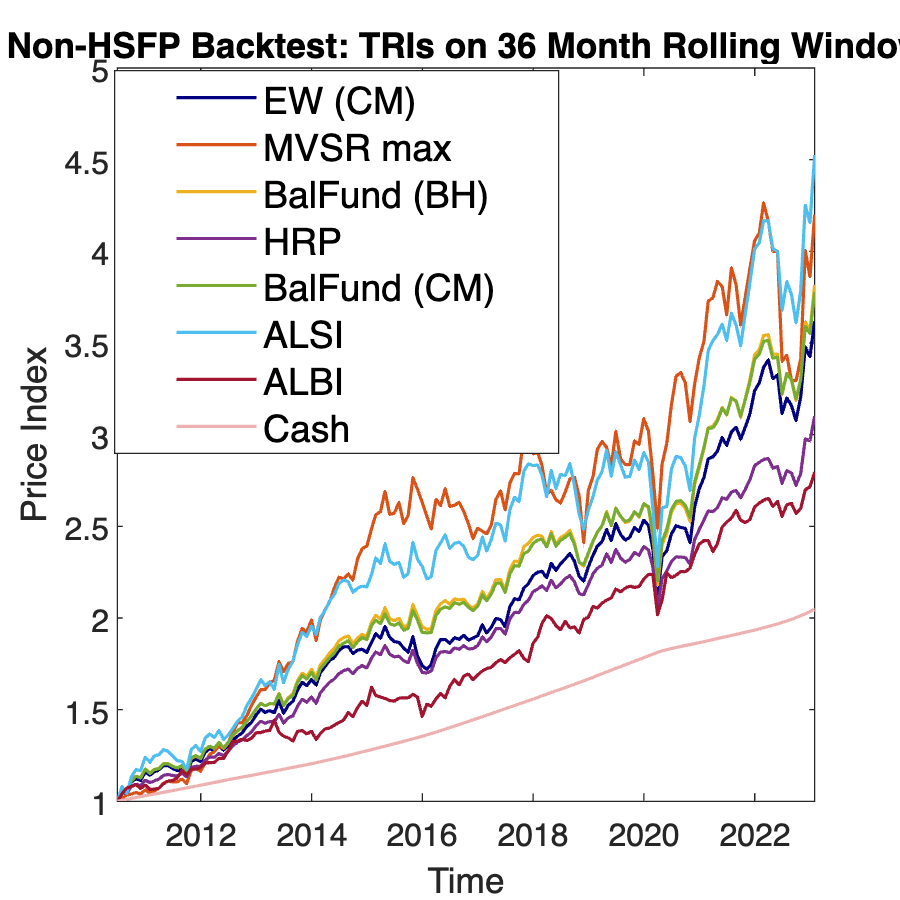

figure('InnerPosition', [100, 100, 600, 600]);

colours = [[0, 0, 0.5];           % blue
    0.8500 0.3250 0.0980;  % orange
    0.9290 0.6940 0.1250;  % yellow,
    0.4940 0.1840 0.5560;  % purple
    0.4660 0.6740 0.1880;  % green
    0.3010 0.7450 0.9330;  % light blue
    0.6350 0.0780 0.1840;  % red
    0.9290 0.6940 0.6940]; % new color (light pink)

numLines = size(Rolling_portfolioSet, 2);
for i = 1:numLines
    lineColor = colours(mod(i-1, size(colours, 1))+1, :);
    plot(Rolling_portfolioSet.Time, Rolling_portfolioSet{:, i}, 'LineWidth', 1.2, 'Color', lineColor);
    hold on;
end

ylabel('Price Index', 'FontSize', 15);
xlabel('Time', 'FontSize', 15);
title(['Non-HSFP Backtest: TRIs on ', num2str(Window), ' Month Rolling Window'], 'FontSize', 16);
legend(Rolling_portfolioSet.Properties.VariableNames, 'Location', 'northwest', 'FontSize', 14);
set(gca, 'FontSize', 12);
UnAdj_36RollW_Output_Plot = gcf;
hold off;

legend("Position", [0.17173,0.5673,0.36486,0.2424])

legend("Position", [0.1896,0.58723,0.36979,0.2424])

## 4. Calculation of Portfolio Attribution

**Return Measures**

- Annualised returns

- Annualised volatility

- Annualised Sharpe Ratio

**Risk Measures**

- CVaR

- Max Drawdown

GRet_EW = Realised_tsPRet{1,1};
exportName = 'test_annual_returns_EW_PRet';
writematrix(GRet_EW,fullfile(dataExportpath,exportName));

### 4.1 Annualised Returns

Geometric average or annualised return


$$ $\quad r_G=\left(\prod_{i=1}^n\left(1+r_i\right)\right)^{\frac{f}{n}}-1$
$$


where: n the number of periods under analysis

f the number of periods within the year (monthly f 12, quarterly f 4).

*(Test case Rolling Window using SA Money Supply with window length of 12 months in a 36 month rolling window backtest.)*

% AnnPRet = zeros(1,length(Realised_tsPRet));
% f = 12; % Number of periods within a year (e.g., 12 for monthly)
% 
% for port = 1: length(Realised_tsPRet)
% 
%     PRet = Realised_tsPRet{2,port};
%     % Number of periods under analysis
%     n = height(PRet);
%     % Calculate the geometric mean return (in decimals)
%     AnnPRet(port) = ((prod(1 + PRet))^ (f / n)) - 1;
%     % Can also use geo_ave for annualisation fn if f set to 12. 
% end

% NOTE: remove first row of Realised returns as that is a false 0 return
AnnPRet = geo_ave(Realised_tsPRet(2:end, :),12)

#### 4.1.1 PRet cell array to TT

% % Initialize an empty cell array to store timetables
% timetables = cell(1, length(Realised_tsPRet));
% 
% % Loop through each cell in the cell array
% for i = 1:length(Realised_tsPRet)
%     data = Realised_tsPRet{2, i};  % Get the data from the cell
%     variableName = Realised_tsPRet{1, i};  % Use the name from the first row of Realised_tsPRet
% 
%     % Store the data in the cell array
%     timetables{i} = data;  
% end
% 
% % Create a timetable from the cell array, assuming timeVector is your actual time data
% timeVector = Rolling_portfolioSet.Time;
% PRet_TT = timetable(timeVector, timetables{:}, 'VariableNames', Realised_tsPRet(1, :));

#### 4.1.2 OptWts cell array to TT

% Initialize an empty cell array to store timetables
timetables = cell(1, length(Opt_tsWts));

% Loop through each cell in the cell array
for i = 1:length(Opt_tsWts)
    data = Opt_tsWts{2, i};  % Get the data from the cell
    variableName = Opt_tsWts{1, i};  % Use the name from the first row of Realised_tsPRet
    
    % Store the data in the cell array
    timetables{i} = data;  
end

% Create a timetable from the cell array, assuming timeVector is your actual time data
timeVector = Rolling_portfolioSet.Time;
OptWts_TT = timetable(timeVector, timetables{:}, 'VariableNames', Opt_tsWts(1, :));

OptWts_array = table2array(OptWts_TT);

### 4.2 Annualised Volatility

Test case Rolling Window using SA Money Supply with window length of 12 months in a 36 month rolling window backtest

AnnPRisk = zeros(1, width(Realised_tsPRet));

for port = 1:width(Realised_tsPRet)
    RealisedRet = Realised_tsPRet{:, port};
    AnnPRisk(port) = sqrt(12) * sqrt(var(RealisedRet)); % Calculate annualized risk
end

% PMean = zeros(1,length(Realised_tsPRet));
% 
% for port = 1: length(Realised_tsPRet)
% 
%     PMean(port) = mean(Realised_tsPRet{2,port});
% end

% PVar = zeros(1,length(Realised_tsPRet));
% for port = 1: length(Realised_tsPRet)
% 
%     PVar(port) = sqrt(var(Realised_tsPRet{2,port}));
% end

### 4.3 Visualise Risk/Return Relationship

% scatter(AnnPRet,AnnPRisk,Rolling_portfolioSet.Properties.VariableNames);
% clf;portfolioexamples_plot('Realised Risk and Return', ...
%     {'scatter',sqrt(diag(PRetCovar)),PMean', Rolling_portfolioSet.Properties.VariableNames, '.b'});

scatter(AnnPRisk,AnnPRet, 300, '.b')
ylabel('Geometric Annualised Returns', 'FontSize', 13)
xlabel('Annualised Standard Deviation', 'FontSize', 13)
title('Realised Portfolio Risk and Return', 'FontSize', 13)
% make data labels:
text((AnnPRisk+0.002),AnnPRet+0.002,{'EW (CM)', 'MVSR max', 'BalFund (BH)', 'HRP', 'BalFund (CM)', 'ALSI', 'ALBI', 'Cash'}, 'FontSize', 9)
grid on
NonHSFP_RealisedAnnRisk_Return_scatter = gcf;

**Export Unconstrained Traditional Optimal Weight Surface Plot**

exportName = 'NonHSFP_RealisedAnnRisk_Return_scatter.pdf';
exportgraphics(NonHSFP_RealisedAnnRisk_Return_scatter,fullfile(imageExportpath,exportName),'Resolution',300);

SR_dif_t =     0.0577    0.0134    0.0577    0.0402    0.0577
   -0.0208    0.0091   -0.0156   -0.0062   -0.0161
    0.0509    0.0012    0.0503    0.0289    0.0502
    0.0123    0.0029    0.0200    0.0081    0.0203
   -0.0145   -0.0117   -0.0142   -0.0128   -0.0142
    0.0376    0.0163    0.0396    0.0232    0.0391
   -0.0195   -0.0218   -0.0249   -0.0166   -0.0248
    0.0112    0.0086    0.0135    0.0038    0.0128
    0.0040    0.0080    0.0006    0.0041    0.0005
    0.0155    0.0218    0.0173    0.0137    0.0172


## 5. 1 Sharpe Ratio

This uses the geometric average of the excess returns series making it a ex-post SR.

SR_dif_t

geo_SR_dif =     1.6581    1.3993    1.7454    1.5688    1.8220


geo_SR_dif

## 5.2 Probabilitic Sharpe Ratio


$$\widehat{P S R}\left(S R^*\right)=Z\left[\frac{\left(\widehat{S R}-S R^*\right) \sqrt{n-1}}{\sqrt{1-\hat{\mu}_3 \widehat{S R}+\frac{\hat{\mu}_4-1}{4} \widehat{S R}^2}}\right]$$


***NOTE: In the backtest set up we calculate an annualised SR.... Are we calculating PSR on an annualised basis as well?***

In the backtest we used cssh as the benchmark ${\textrm{SR}}^*$ here we can first use 0 as the measure of  comparing against no investment skill.


$$\widehat{P S R}\left(S R^*\right)= Pr[S R \leq \widehat{S R}]=\int_{-\infty}^{\widehat{S R}} Z\left(S R \mid S R^*, \hat{\sigma}_{\widehat{S R}}\right) \cdot d S R$$


format longG

#### Remove '0' in realised returns

% Remove the first row from the timetable
Realised_tsPRet(1, :) = [];

### 5.1 Test components: Estimate Sharpe Ratio (geo_sr.m) CONFIRMED using EW port

Rolling_portfolioSet.Properties.VariableNames
% TEST GEOMETRIC AVERAGE - set f = 1 so it is just geometric mean and not annualised using f = 12

ans = 1×8 cell array
    {'EW (CM)'}    {'MVSR max'}    {'BalFund (BH)'}    {'HRP'}    {'BalFund (CM)'}    {'ALSI'}    {'ALBI'}    {'Cash'}


test_geo_ave = geo_ave(Realised_tsPRet.("EW (CM)"),1)
test_std = std(Realised_tsPRet.("EW (CM)"),1) %% NB: need to decide about /(N-1) or /N

test_geo_ave = 0.0086

test_sr =test_geo_ave/test_std

test_std = 0.0279

% set f = 1 so it is just geometric mean and not annualised using f = 12

test_sr = 0.3063

[geo_SR,geo_ExcessRet_ave,ExcessRet_sd] = geo_sr(Realised_tsPRet.("EW (CM)"))

geo_SR = 0.3063

geo_ExcessRet_ave = 0.0086

ExcessRet_sd = 0.0279

### 5.2 Test components: sr_std.m Standard deviation of SR: CONFIRMED

NOTE: sr_std only does 1 asset at a time, not full tables.

% Standard Normal dist needs skewness (mu3) = 0 & kurtosis (mu4) = 3 
[ srStd, skew, kurt,T] = sr_std(Realised_tsPRet.("EW (CM)"), 151,0,3)

srStd = 0.0835

skew = 0

kurt = 3

T = 151

### 5.3 Test components: PSR

NOTE: psr only does 1 asset at a time, not full tables.

mv_sr = geo_sr(Realised_tsPRet.("EW (CM)"),1)
mv_sr_Std = sr_std(Realised_tsPRet.("EW (CM)"))

mv_sr = 0.3063

eval_sr = normcdf((mv_sr - 0) / mv_sr_Std)

mv_sr_Std = 0.0876

eval_sr = 0.9998

### 5.4 Call PSR: 

test_psr = psr(Realised_tsPRet.("MVSR max"), 0)

test_psr = 0.9966

format shortG

### 5.5 Export Strategy-wise PSRs:

For each strategy create a cross tab of the strategy sr and alternative benchmark strategy:

J = size(Realised_tsPRet,2);
port_psr = zeros(J,J);


for strategy = 1:J
    for bench_port = 1:J
        port_psr(strategy, bench_port) = psr(Realised_tsPRet{:, strategy}, Realised_tsPRet{:, bench_port});
    end
end


Portfolio_Names = string(strrep(Rolling_portfolioSet.Properties.VariableNames, '_', ' '));
% Add variable names to the first row and first column of port_psr
port_psr = [Portfolio_Names; port_psr]; % Add variable names as the first row
% port_psr = [Portfolio_Names'; port_psr]; % Add variable names as the first column
port_psr

port_psr = 9×8 string array
    "EW (CM)"    "MVSR max"    "BalFund (BH)"    "HRP"        "BalFund (CM)"    "ALSI"       "ALBI"       "Cash"
    "0.5"        "0.82642"     "0.49977"         "0.39613"    "0.42548"         "0.73398"    "0.48013"    "0"   
    "0.1659"     "0.5"         "0.16575"         "0.10704"    "0.12212"         "0.37244"    "0.1534"     "0"   
    "0.50024"    "0.82888"     "0.5"             "0.39538"    "0.425"           "0.73614"    "0.48017"    "0"   
    "0.59347"    "0.86004"     "0.59326"         "0.5"        "0.52702"         "0.78742"    "0.57602"    "0"   
    "0.57419"    "0.86926"     "0.57396"         "0.47005"    "0.5"             "0.79078"    "0.55466"    "0"   
    "0.25181"    "0.63208"     "0.25161"         "0.17088"    "0.19218"         "0.5"        "0.23511"    "0"   
    "0.51847"    "0.8213"      "0.51826"         "0.42131"    "0.44893"         "0.73476"    "0.5"        "0"   
    "1"          "1"           "1"               "1"          "1"   

### 5. 6 Export NO investment skill PSRs:

For each strategy create a cross tab of the strategy sr and alternative benchmark strategy:

J = size(Rolling_portfolioSet,2);
base_psr = zeros(J,J);
for strategy = 1:J
    for bench_port = 1:J
        base_psr(strategy, bench_port) = psr(Realised_tsPRet{:, strategy}, 0);
    end
end

base_psr

base_psr =     0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998
    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958
    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998
    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996
    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999
    0.9989    0.9989    0.9989    0.9989    0.9989    0.9989    0.9989    0.9989
    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


port_base_psr = psr(Realised_tsPRet.("MVSR max"), 0);

Thin this works as cash PSR = 1 against a no investment strat of SR* = 0 which makes sense as there is return but zero risk with cash.

### 5.6.1 Export latex table

sympref('FloatingPointOutput',1);
latex_table = latex(sym(round(port_psr,4 )));
